MECE6397: Learning-Based Control 

# Homework 7: Reinforcement Learning for Feedback Control

Instructor: Marzia Cescon

## 1. Introduction to Reinforcement Learning

In previous modules we have designed controllers capable of learning to control an unknown system using data collected from the system during operation. Gain scheduling and MRAC are examples of controllers adapting their parameters with the measured data, while ILC learns the control actions from data in a batch-wise mode. Such adaptive controllers were not designed to be optimal in the sense of minimizing user-prescribed performance indexes (for details, please consult [1],[2]). This homework will show that the tecnique known as **Reinforcement Learning** allows one to design feedback controllers combining features of adaptive control and optimal control [3 (Chapter 11), 4]. Specifically, RL refers to a class of methods from machine learning that can be used to design adaptive controllers which can learn online the solution to user-prescribed optimal control problems.The principles behind RL originate from the learning mechanisms we see in nature and are based on the idea that we learn by interacting with our environment, adjusting our actions based on how our environment responds to what we do. In this framework, RL becomes a means of learning optimal behaviors by observing real-time responses from the environment to non-optimal control actions. 

More precisely, in machine learning, RL is a method for solving optimization problems that involves an *actor* or *agent *that interacts with its *environment* and modifies its *actions, *or *control policies, *on the basis of *rewards* received in response to the actions. Figure 1 gives a schematic illustration of the concept with one example.

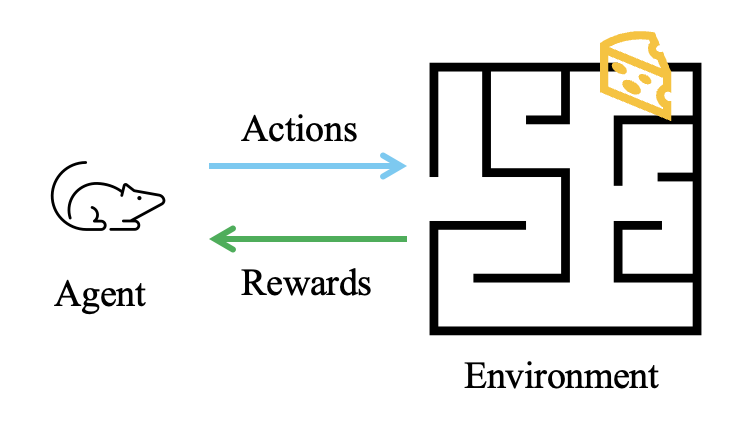

Figure 1. Reinforcement Learning in navigating a maze.

The *agent* (mouse) aims at solving a task (navigating the maze and reach the exit) by taking *actions* (move forward, left, right) in a trial-and-error manner and receiving a reward (cheese) or penalty (hit a wall) from the *environment* (maze) based on its behavior. In this illustrative example, the building blocks of RL are the following:

- **Agent**: mouse

- **State**: current position of the mouse within the maze

- **Environment**: maze with multiple paths, dead ends and a single exit leading to a reward (cheese)

- **Actions**: move forward, turn left, turn right

- **Reward**: positive for reaching the exit, negative for hitting a wall, and zero for all other movements

The RL process entails exploration: the mouse initially explores the maze randomly, trying different paths corresponding to different actions. It also involves learning through experience of repeated attempts. When a mouse reaches a dead-end of hits a wall, it receives a penalty (negative reward) which discourages taking that path again. When the mouse successfully navigates the maze and finds the cheese, it receives a positive reward which reinforces the successful path. Over time, the mouse starts favoring paths that lead to the cheese, avoiding those that lead to dead-ends or penalties. This enables the mouse to gradually learn a strategy (**policy**) for navigating the maze that maximizes the overall reward.

The key RL concepts presented by this examples are:

- **Exploration vs. exploitation tradeoff: **the mouse balances exploring new paths with exploiting known paths that have previously yielded rewards

- **Policy**: the strategy learned by the mouse to navigate the maze. 

For a more in-depth overview of RL, check the MATLAB Ted Talks video series [Reinforcement Learning](https://www.mathworks.com/videos/series/reinforcement-learning.html). To learn the basics of creating controllers that learn from experience in MATLAB, go to the [Reinforcement Learning Onramp](https://matlabacademy.mathworks.com/details/reinforcement-learning-onramp/reinforcementlearning).

## 2. Markov Decision Processes (MDPs)

A natural framework to study RL is provided by Markov Decision Processes (MDPs) [3, Chapter 11]. A MDP is a tuple ($X,U,P,R$), where:

- $X$ is a set of states

- $U$ is a set of actions or controls

- $P$ is a set of transition probabilities 

- $R$ is a set of costs

The transition probabilities $P:X\times U\times X\to \left\lbrack 0,1\right\rbrack$ give for each state $x\in X$ and action $u\in \;U$the conditional probability $P_{xx^{\prime } }^u =\Pr \;\left\lbrace x^{\prime } |x,u\right\rbrace$of transitioning to state $x^{\prime } \in X$ given the MDP is in state $x$ and takes action $u$. The cost function $R:X\times U\times X\to \mathbb{R}$ gives the expected immediate cost $R_{xx^{\prime } }^u$ paid after transition to state $x^{\prime } \in X$ given the MDP is in state $x$ and takes action $u$. The Markov property refers to the fact that transition probabilities $P_{x\;x^{\prime } }^u$ depend only on the current state $x$ and not on the history of how the MDP attained that state. The basic problem for MDP is to find a mapping $\pi :X\times U\to \left\lbrack 0,1\right\rbrack$ that, for each state $x$ and action $u$, gives the conditional probability $\pi \left(x,u\right)=\Pr \;\left\lbrace u\;|\;x\right\rbrace$of taking action $u$ given the MDP is in state $x$. Such a mapping is referred to as a *closed-loop control *or *policy*. 

We consider MDPs evolving in discrete-time and introduce a discrete stage index $k$. An objective of MDP is to determine an *optimal policy* $\pi^* \left(x,u\right)$ that minimizes the expected future cost: 

 $\pi^{\;*\;} \left(x,u\right)=\;\underset{\pi \;}{\textrm{argmin}} \;{\mathbb{E}}_{\pi \;} \left\lbrace \sum_{i=k}^{k+T} \gamma^{i-k} \;r_i \;|\;x_k =x\right\rbrace$, 

with $r_k =r_k \left(x_k ,u_k ,x_{k+1} \right)\;$stage cost at time $k$, and$\;0\le \gamma \le 1\;$a discount factor that reduces the weight of costs incurred in the future. The corresponding optimal value is given as:

$V_k^* \left(x\right)=\min_{\pi } \;V_k^{\pi } \left(x\right)=\min_{\pi }$${\mathbb{E}}_{\pi \;} \left\lbrace \sum_{i=k}^{k+T} \gamma^{i-k} \;r_i \;|\;x_k =x\right\rbrace$.

A backward recursion for the optimal value at time $k$ in terms of the optimal value at time $k+1$can be written [3, Chapter 11]. It can be shown that by using the Chapman-Kolmogorov identity, the Markov property and the Bellman's optimality principle, the optimal value and optimal policies can be expressed as a function of the complete system dynamics denoted by the transition probabilities $P_{xx^{\prime } }^u$and expected costs $R_{xx^{\prime } }^u$ (details omitted here, please consult [3, Chapter 11]):

$V_k^* \left(x\right)=\min_u \;\sum_{x^{\prime } } P_{xx^{\prime } }^u \left\lbrack R_{xx^{\prime } }^u +\gamma V_{k+1}^* \left(x^{\prime } \right)\right\rbrack$,


$$u_k^* =\underset{u}{\textrm{argmin}} \sum_{x^{\prime } } P_{xx^{\prime } }^u \left\lbrack R_{xx^{\prime } }^u +\gamma V_{k+1}^* \left(x^{\prime } \right)\right\rbrack \ldotp$$
 

These backward recursions form the basis of Dynamic Programming (DP). To derive forward-in-time methods for finding optimal values and optimal policies, which is relevant for reinforcement learning, we set the time horizon $T=\infty$. The associated infinite-horizon value function for the policy $\pi \left(x,u\right)$ is $V^{\pi } \left(x\right)={\mathbb{E}}_{\pi \;} \left\lbrace \sum_{i=k}^{\infty } \gamma^{i-k} \;r_i \;|\;x_k =x\right\rbrace$, which satisfies the *Bellman equation, *in which the same value function appears on both side of the equation:

$V^{\pi } \left(x\right)=\sum_u \pi \left(x,u\right)\sum_{x^{\prime } } P_{xx^{\prime } }^u \left\lbrack R_{xx^{\prime } }^u +\gamma V^{\pi } \left(x^{\prime } \right)\right\rbrack$.

The solution to the Bellman equation gives the value function of a specific policy $\pi \left(x,u\right)$. The Bellman equation is exploited in methods known as *policy iteration* and *value iteration* to find optimal policies by using causal experiences received stagewise forward in time. To perform the value and policy updates for policy iteration and value iteration, the main methods adopted are Monte Carlo methods and Temporal Difference Learning. For details of these algorithms please consult [5].

### 2.1. Q Function

The conditional expected value in the optimal value equation is known as the optimal *Q function:*

$Q_k^* \left(x,u\right)=\sum_{x^{\prime } } P_{xx^{\prime } }^u \left\lbrack R_{xx^{\prime } }^u +\gamma V_{k+1}^* \left(x^{\prime } \right)\right\rbrack =$${\mathbb{E}}_{\pi \;} \left\lbrace r_k +\gamma V_{k+1}^* \left(x^{\prime } \right)|x_{k\;} =x,u_k =u\right\rbrace$.

The Q function explains the expected return for taking an arbitrary action $u$ at time $k$ while in state $x$ and thereafter following an optimal policy. It is a function of the current state $x$ and the action $u$. Substituting $Q_k^* \left(x,u\right)$ above we obtain:

$V_k^* \left(x\right)=\min_u {\;Q}_k^* \left(x,u\right)\;$,


$$u_k^* =\underset{u}{\textrm{argmin}} \;Q_k^* \left(x,u\right)\ldotp$$


For finite MDPs, i.e., MDPs with finite state and action spaces, the Q function can be stored as a lookup table for each state/action pair. A useful property of the Q function is that it can be estimated online in real time, without knowing the system dynamics, by measuring data along the system trajectories. In the next section of this homework we will see how this is accomplished in MATLAB.

### 2.2. Train a Q-learning agent in a MDP environment

This example is a modified version of Stage 1 in [6]. It shows how to train a Q-learning agent in a generic MDP environment. For more information on these agents, see [Q-Learning Agent](https://www.mathworks.com/help/reinforcement-learning/ug/q-learning-agents.html).

The problem is illustrated in Figure 1. The agent aims at reaching the closest of the two terminal states (S1 and S8) by taking actions (move either left or right) in a trial-and-error manner without stopping at one place, and receiving a reward (+10) or penalty (-1) from the environment based on reaching a terminal state or non terminal state, respectively. 

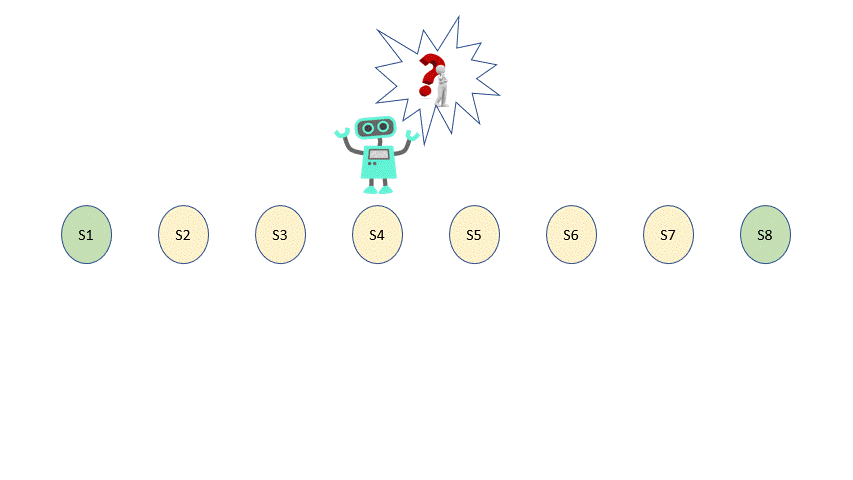

Figure 1: MDP problem

- **Goal**: reach to the nearest terminal point

- **States**: 8 states with 2 terminal states and 6 non terminal states

- **Actions**: move left, move right

- **Reward**: + 10 for reaching the terminal states, -1 for reaching non terminal states 

We start by creating a MATLAB environment for the problem. 

**Task 1. **Fill in the blanks with the values of the parameters defining States, Actions, Rewards and Transition Probabilities.

States = ; % states

Actions = [ , ]; %actions the agent can take 

RewardNT = ; % reward for non-terminal states 

RewardT = ; % reward for terminal states

Transition_Probability = ; % transition probability is 1 for all actions

**Task 2. **Use the function [`createMDP(states,actions)`](https://www.mathworks.com/help/reinforcement-learning/ref/createmdp.html#d123e1992) to create an MDP object, and store it in a variable named MDP. Note that states and actions for our case have been already defined in Task 1.

% Enter Code Here.

Let us now investigate the properties of the environment by accessing states, actions, rewards and transitions probabilities from the generic MDP object defined in Task 2.

**Task 3**. Show the strings of states and actions, respectively, and the 3D-array specifying state and reward transtion matrices, respectively. What do you observe?

% Enter Code Here. 

After creating a variable MDP of the dimensions of our model, we now update it to fit our problem formulation.

**Task 4.** Specify states `"s1"` and `"s8"` as terminal states of the MDP.

% Enter Code Here.

Next, we store the non terminal states in a variable named `NonTerminalstates`. We do so by getting the data in `MDP.States` that is not in `MDP.TerminalStates` using the function [`setdiff(A,B)`](https://www.mathworks.com/help/matlab/ref/double.setdiff.html#d123e1301163)`:`

NonTerminalStates= setdiff(MDP.States,MDP.TerminalStates)

To model the transitions from one state to the next in the model depicted in Figure 1, we modify the state transition matrix and reward matrix of the MDP. By default, these matrices contain zeros. For example, in the following commands:

- The first two lines specify the transition from state 1 to state 2 by taking action `1` ("left") and a reward of +3 for this transition.

- The next two lines specify the transition from state 1 to state 3 by taking action `2` ("down") and a reward of +1 for this transition.

MDP.T(1,2,1) = 1;
MDP.R(1,2,1) = 3;
MDP.T(1,3,2) = 1;
MDP.R(1,3,2) = 1;

**Task 5.**  Specify the values for the reward array R. Begin with assigning a reward of -1, stored in the variable `RewardNT`, for all the action in all the states.

% Enter Code Here.

We can now change the reward for the terminal states:

MDP.R(:,state2idx(MDP,MDP.TerminalStates),:)= RewardT

**Task 6.** Specify the values for the transition probabilites for each state, filling in the blanks below:

% State 1 transition
MDP.T(1,1,1) = ;
MDP.T(1,2,2) = ;

% State 2 transition


% State 3 transition


% State 4 transition


% State 5 transition


% State 6 transition


% State 7 transition


% State 8 transition



**Task 7.** Create now the reinforcement learning environment for this process model using the function [`rlMDPEnv(MDP)`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.env.rlmdpenv.html#d123e17882)and the MDP object created above. Store it in a variable named `env`.

% Enter Code Here.

We store the values of number of states and number of actions, respectively, in two variables, exploiting the MATLAB built-in function [`numel`](https://www.mathworks.com/help/matlab/ref/double.numel.html#d123e914058):

number_of_states= numel(MDP.States)
number_of_actions= numel(MDP.Actions)

To create a Q-learning agent, first create a Q table model using the observation and action specifications from the MDP environment. We use functions [`getObservationInfo`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.env.basicgridworld.getobservationinfo.html) and [`getActionInfo`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.env.basicgridworld.getactioninfo.html) to retrieve the needed observations and actions information:

stateInfo = getObservationInfo(env);
actionInfo = getActionInfo(env);

**Task 8.** Create a Q table using the function [`rlTable`](https://www.mathworks.com/help/reinforcement-learning/ref/rltable.html#d123e25994), with observations and actions from above, and store it in a variable named `qTable`*. *After that, display the Q table.

% Enter Code Here.

**Task 9.** Next create a Q-value *critic* function from the table model using the function [`rlQValueFunction`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.function.rlqvaluefunction.html)`. `Store it in a variable named `qFunction. `Display the` Options `property of this critic function.

% Enter Code Here.

**Task 10.** Finally, create the Q-learning agent using this critic function. Use the function [`rlQAgent`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.agent.rlqagent.html)`.` Store it in a variable named `qAgent. `To specify options for this agent,` u`se an  [`rlQAgentOptions`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.option.rlqagentoptions.html) object`. `For this training:

- Specify a discount factor of 1.0 to favor undiscounted long term rewards.

- Specify the initial epsilon value 0.9 for the agent's epsilon greedy exploration model.

- Specify a decay rate of 1e-3 and the minimum value of 0.1 for the epsilon parameter. Decaying the exploration gradually enables the agent to exploit its greedy policy towards the latter stages of training.

- Use the stochastic gradient descent with momentum (`sgdm`) algorithm to update the table model with the learning rate of 0.1. 

- Using the L2 regularization factor 0. For this example disabling regularization helps in better estimating the long term undiscounted rewards.

Fill in the blanks below.

agentOpts = ;
agentOpts.DiscountFactor = 1;



agentOpts.CriticOptimizerOptions = rlOptimizerOptions( ...
    Algorithm="sgdm", ...
    LearnRate = 0.1, ...
    L2RegularizationFactor = 0);
qAgent = ;

To train the agent, we first specify the training options`. `

**Task 11.** Create a variable named` trainOpts `using the function [`rlTrainingOptions`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.option.rltrainingoptions.html)`.`For this example, use the following options:

- Train for 400 episodes, with each episode lasting at most 50 time steps.

- Specify a window length of 30 for averaging the episode rewards.

Fill in the blanks.

trainOpts.MaxStepsPerEpisode = ;
trainOpts.MaxEpisodes = ;
trainOpts.StopTrainingCriteria = "AverageReward";
trainOpts.StopTrainingValue = 13;
trainOpts.ScoreAveragingWindowLength = 30;
trainOpts = ;

We now train the agent using the [`train`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.agent.rlqagent.train.html) function:

doTraining = true;

if doTraining
    % Train the agent.
    trainingStats = train(qAgent,env,trainOpts); %#ok<UNRCH> 
else
    % Load pretrained agent for the example.
    load('genericMDPQAgent.mat','qAgent'); 
end

**Task 12.** To verify the training results, simulate the agent in the training environment using the [`sim`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.env.abstractenv.sim.html) function. What is the cumulative reward?

% Enter Code Here.

Enter your text here.

## 3. Off-policy actor-critic methods for continuous action-space environments

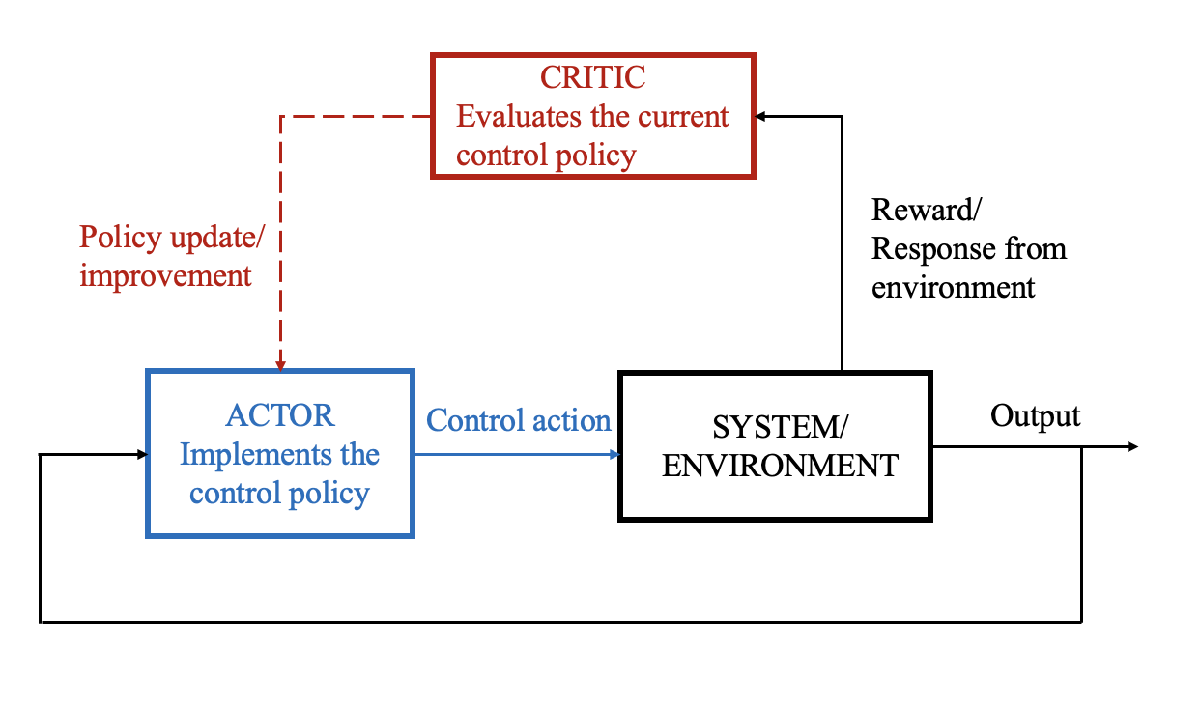

Figure 2. Reinforcement learning with actor-critic structure.

Figure 2 shows one type of reinforcement learning algorithms with *actor-critic* structure [7]. In this structure an actor component applies a control policy to the environment, and a critic component evaluates the value of that action. The learning mechanism supported by the actor-critic structure has two steps: policy evaluation by the critic, followed by policy improvement by the actor. More details in [4]. In this example we will learn how to train a biped robot to walk using two methods based on the actor-critic structure, implementing deep reinforcement learning, namely deep deterministic policy gradient (DDPG) and twin-delayed deep deterministic policy gradient (TD3), and we will compare the performance of these two methods. The robot is modeled in Simscape™ Multibody™. For more information on these agents, see [Deep Deterministic Policy Gradient (DDPG) Agent](https://www.mathworks.com/help/reinforcement-learning/ug/ddpg-agents.html) (Reinforcement Learning Toolbox) and [Twin-Delayed Deep Deterministic (TD3) Policy Gradient Agent](https://www.mathworks.com/help/reinforcement-learning/ug/td3-agents.html) (Reinforcement Learning Toolbox).

Open the MATLAB example.

openExample('control_deeplearning/TrainBipedRobotToWalkUsingReinforcementLearningAgentsExample')

**Task 13**. Compare the performance of the two methods after running each training session for 3000, 4000, 5000 and 6000 episodes, respectively. What do you observe? What are your comments on the two methods?

Enter your text here.

## References

[1] Åström, K. J.,  and Wittenmark, B. (1995). Adaptive Control. *Addison Wesley*.

[2] Bristow, D. A., Tharayil, M., & Alleyne, A. G. (2006). A survey of iterative learning control. *IEEE control systems magazine*, *26*(3), 96-114. 

[3] Lewis, F. L, Vrabie, D. and Syrmos, V. (2012). Optimal Control, 3rd ed. *Wiley*.

[4] Lewis, F. L., Vrabie, D.  and Vamvoudakis, K. G. (2012). Reinforcement Learning and Feedback Control: Using Natural Decision Methods to Design Optimal Adaptive Controllers. *IEEE Control Systems Magazine*, vol. 32, no. 6, pp. 76-105.

[5] Sutton, R. S. and Barto, A. G. (1998). Reinforcement Learning: An Introduction. Cambridge, MA: MIT Press.

[6] Sahil S. Belsare, Mohammad Dehghani, Rifat Sipahi, (2022). Reinforcement-Learning-RL-with-MATLAB (https://github.com/mdehghani86/Reinforcement-Learning-RL-with-MATLAB/releases/tag/v1.0.0), GitHub. Retrieved Jan 7, 2025.

[7] Barto, A. G., Sutton, R. S. and Anderson, C. W. (1983). Neuronlike adaptive elements that can solve difficult learning control problems. *IEEE Transactions on Systems, Man, and Cybernetics*, vol. SMC-13, no. 5, pp. 834-846.